# Example 1

Prepared for EG-247 Digital Signal Processing by Dr C.P. Jobling

Karris example 8.8: for the linear network shown below, the impulse response is $h(t) = 3e^{-2t}u_0(t)$. Use the Fourier transform to compute the response $y(t)$ when the input $u(t)=2\left[u_0(𝑡)-u_0(𝑡-3)\right]$. Verify the result with MATLAB.

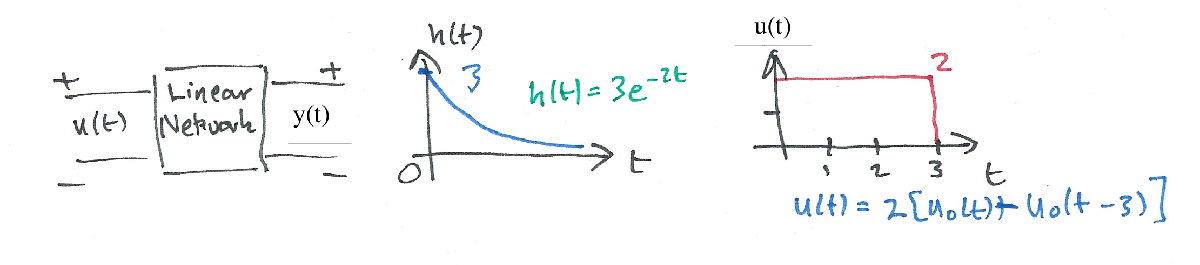

syms t w
U1 = fourier(2*heaviside(t),t,w)

H = fourier(3*exp(-2*t)*heaviside(t),t,w)

Y1=simplify(H*U1)

y1 = simplify(ifourier(Y1,w,t))

## Get y2

substitute t-3 into t.

y2 = subs(y1,t,t-3)

y = y1 - y2

## Plot result

ezplot(y)
title('Solution to Example 1')
ylabel('y(y)')
xlabel('t [s]')
grid